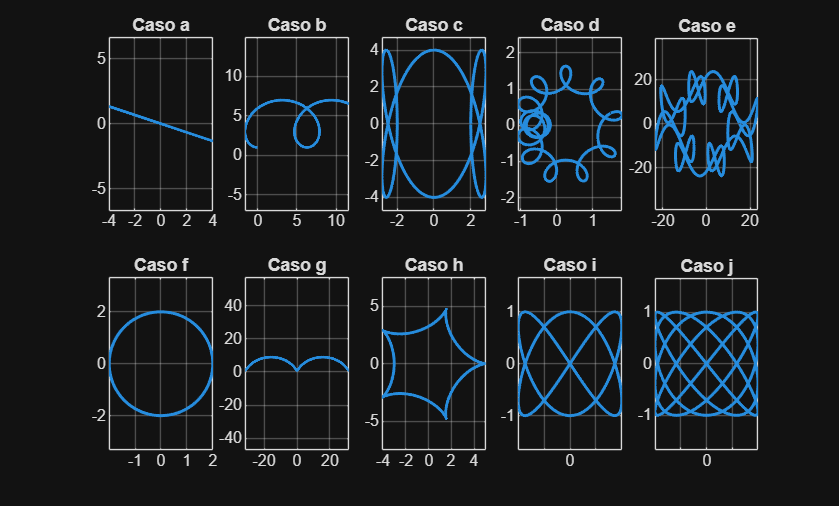

%Limpieza de pantalla
clear all
close all
clc

%Parametrizacion
trayectorias = {"a","b","c","d","e","f"};

for i = 1:length(trayectorias)
    % Definición de t, x, y por casos
    switch trayectorias{i}
        case "a"
            theta = 0: pi/2: 2*pi;
            r = ones(1, 5);
        case "b"
            theta = 0: pi/3: 2*pi;
            r = ones(1, 7);
        case "c"
            theta = 0: pi/6: 2*pi;
            r = ones(1, 13);
        case "d"
            theta = linspace(0, pi, 2000); 
            r = -50 .* sin(7 .* theta); 
        case "e"
            theta = linspace(0, pi, 2000);
            r = 5 .* sin(15 .* theta);
        case "f"
            theta = linspace(0, pi, 2000); 
            r = -5 .* cos(80 .* theta);
    end
    %Graficas
    subplot(2, 3, i);
    polarplot(theta, r, 'LineWidth', 1.5);
    title(['Caso ', letras{i}]);
    grid on;
end